% 读取图像
img = edges_laplacian; % 替换为你的图像文件名

gray_img = img;

gray_img = 258×258 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

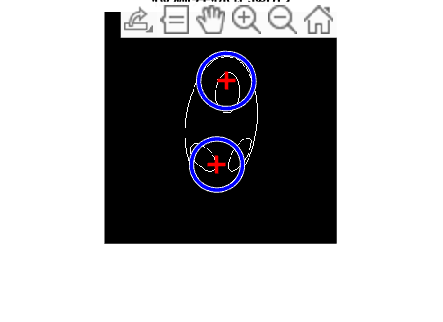


% 使用 Hough 变换检测圆形
[centers, radii] = imfindcircles(gray_img, [20 50], 'ObjectPolarity', 'bright', 'Sensitivity', 0.9);

% 显示原始图像
imshow(img);
hold on;

% 标记检测到的圆形
viscircles(centers, radii, 'EdgeColor', 'b');

% 显示圆心
plot(centers(:,1), centers(:,2), 'r+', 'MarkerSize', 10, 'LineWidth', 2);

hold off;
title('检测并标记圆形');